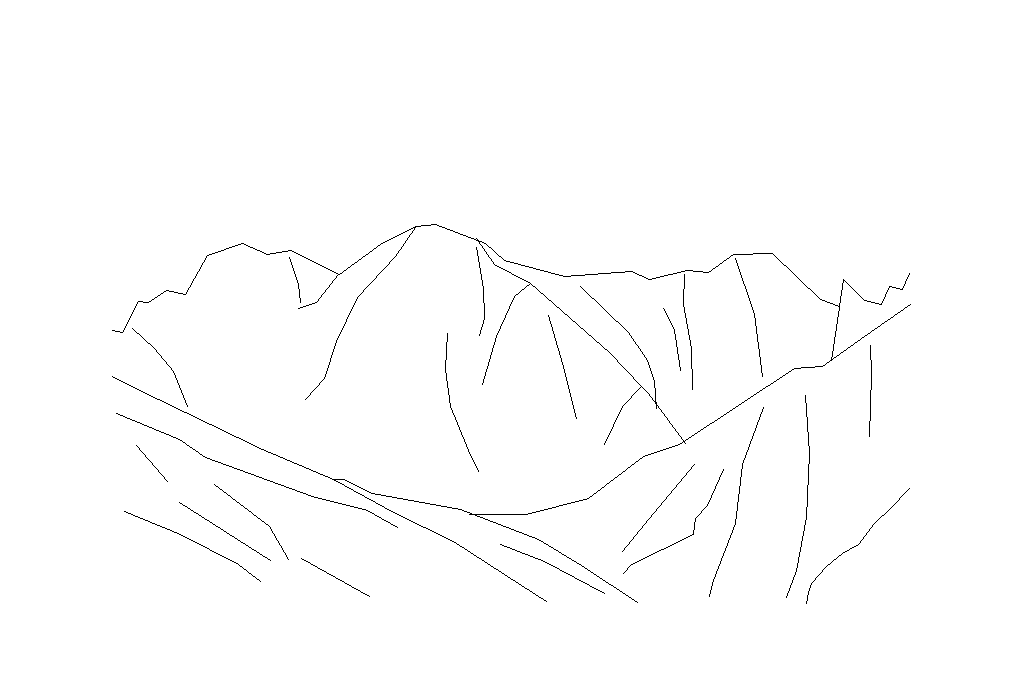

% Please make sure that the current directory is MLV_toolbox

setup


% Choose one image for demonstration
% We use data structure 11 here (row 11) and call it 'cute'!
load('dataSets/TorontoScenes/mountains_vecLD.mat');
cute = vecLD(11);

% Convert the vectorized line drawing into an image
imgLD = renderLinedrawing(cute);

% View 'imgLD'
figure;
imshow(imgLD);

% Compute Medial Axis
MAT = computeMAT(imgLD);

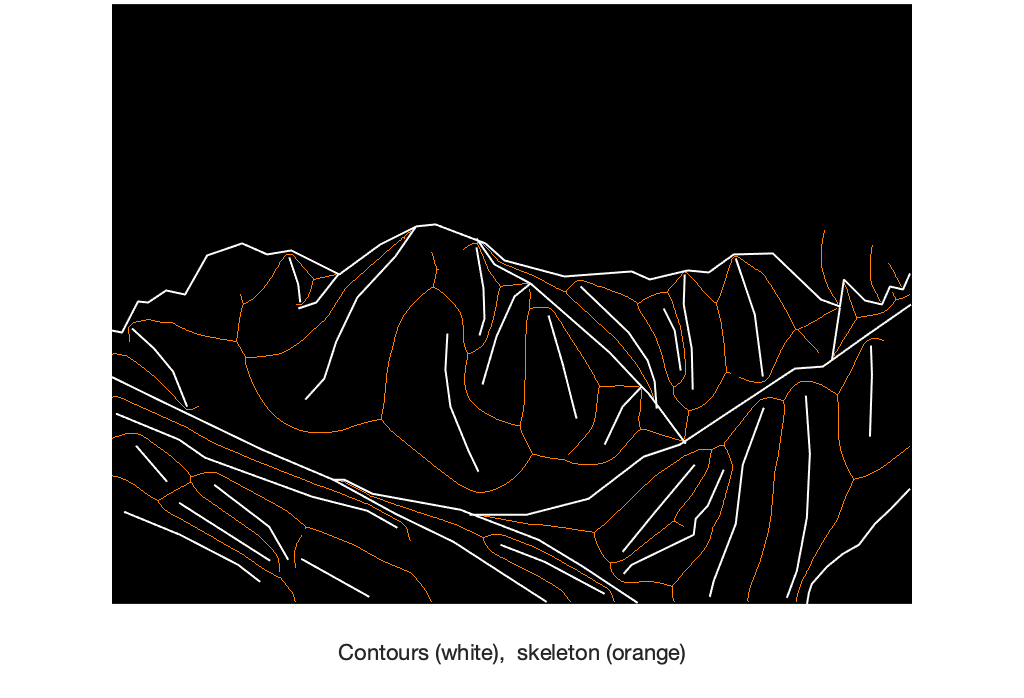

figure;
imshow(cat(3,MAT.skeleton,0.5*MAT.skeleton,zeros(size(MAT.skeleton))));
hold on;
drawLinedrawing(cute,1,'white')
% imshow(imoverlay(imcomplement(rgb2gray(imgLD)),MAT.skeleton,[1,0.5,0]))
xlabel('Contours (white),  skeleton (orange)')

figure;
imagesc(MAT.distance_map);
hold on;
drawLinedrawing(cute,1,'white')
c = colorbar;
c.Label.String = 'Distance to the closest contour'

c =   ColorBar (Distance to the closest contour) with properties:

    Location: 'eastoutside'
      Limits: [-1 270.6677]
    FontSize: 9
    Position: [0.8500 0.1661 0.0286 0.7024]
       Units: 'normalized'

  Show all properties


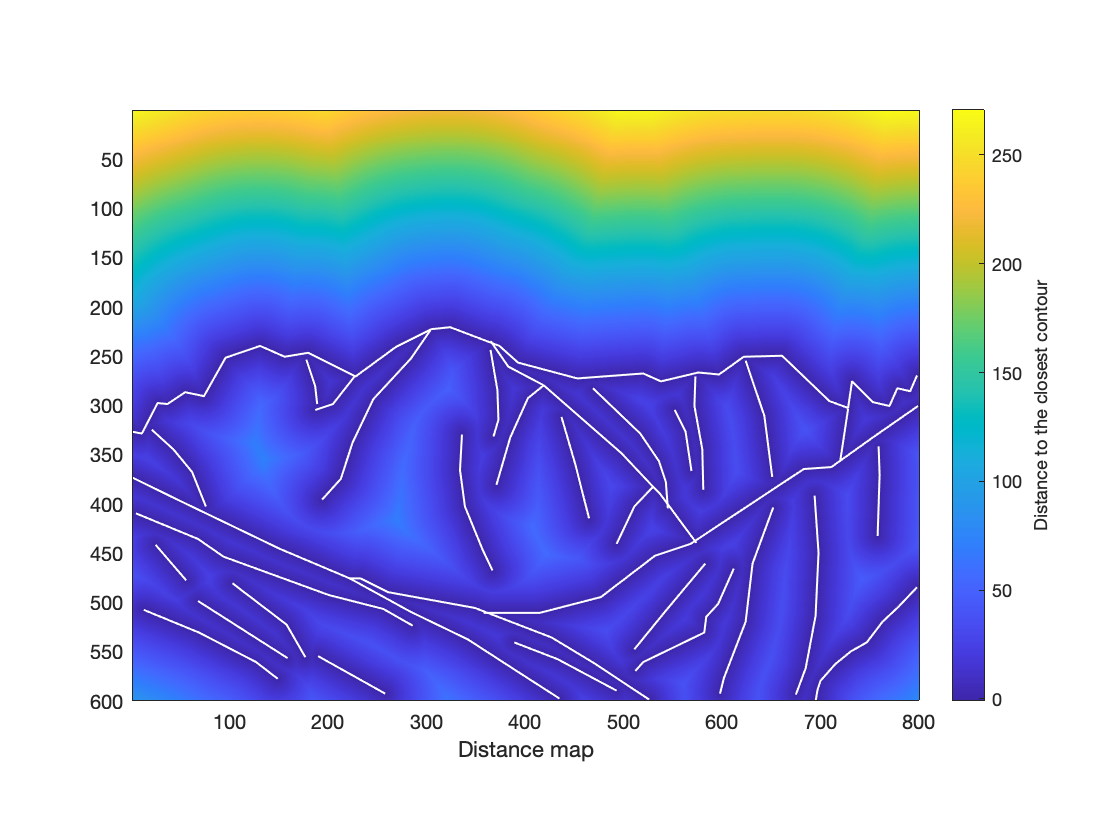

xlabel('Distance map')

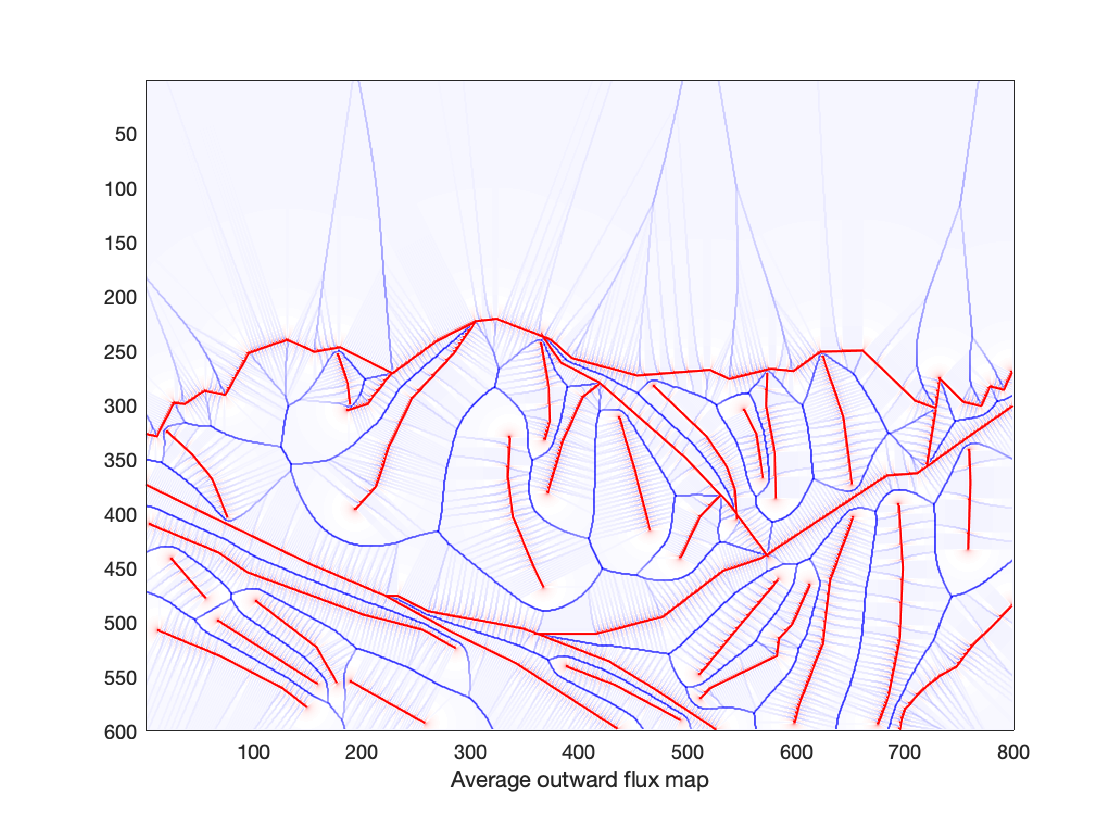

figure;
imagesc(-(MAT.AOF))
colormap redblue
hold on;
drawLinedrawing(cute,1,'red')
xlabel('Average outward flux map')